# Set Plotting Style

set(groot, 'defaultAxesFontSize', 15);

# 5.3 IIR Filtering of Sinusoids

f_s = 1000; % Hz
% sin component
a_1 = 5;
w_1 = 200*pi;
% cos component
a_2 = 2;
w_2 = 300*pi;

N = 300; % samples

% Chebyshev Type II Filter - cheby2
cheb2ord(150/(f_s/2), 100/(f_s/2), 1, 40)

ans = 6

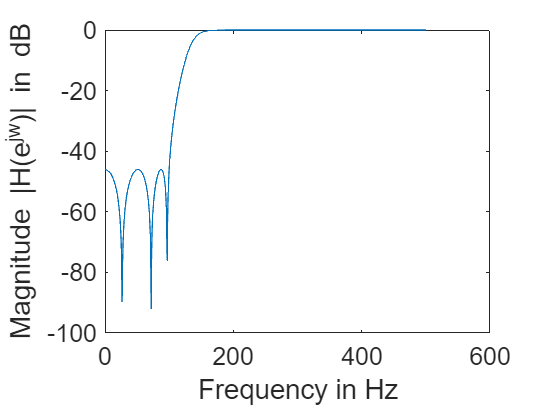


[z,p,k] = cheby2(6, 40, 100/(f_s/2),"high");
[num, den] = zp2tf(z,p,k);
sys = tf(num, den);

[H_cheb, w_cheb] = freqz(num, den, 1e3);
plot(w_cheb*f_s/(2*pi), 10*log(abs(H_cheb)));
xlabel("Frequency in Hz");
ylabel("Magnitude |H(e^{jw})| in dB")

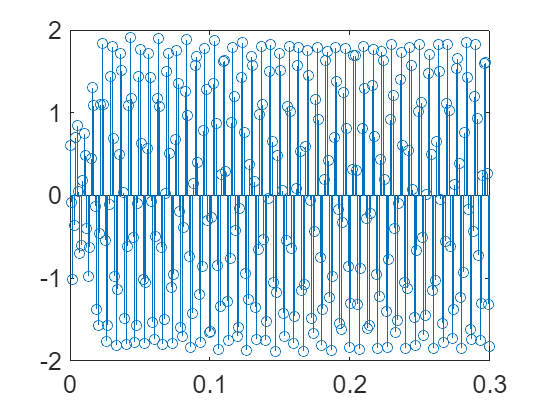

% Filter x(t) with Chebyshev
n = linspace(0, N/f_s, N);
x_n = a_1*sin(n.*w_1)+a_2*cos(n.*w_2);
y_n = filter(num, den, x_n);

stem(n, y_n);

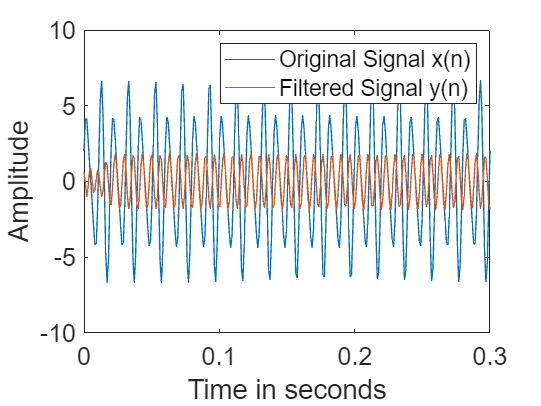


figure;
plot(n, x_n);
hold on;
plot(n, y_n);
hold off;
legend(["Original Signal x(n)", "Filtered Signal y(n)"]);
xlabel("Time in seconds");
ylabel("Amplitude");